# Create and Customize Bubble Cloud Charts

Bubble cloud charts display colored circular markers (bubbles) with varying sizes to illustrate the relationship between elements in a data set.

### Read Population Data

We will use "populationData.`mat" `to demonstrate how to create and customize bubble cloud charts. The MAT-file contains a table of 2020 population data obtained from the World Bank of 216 countries and territories, and each of their regions.

load("populationData.mat")

### Basic Bubble Cloud Chart

View the relationship between the population of each country by specifying the *Population* as the size variable and *Country* as the label.

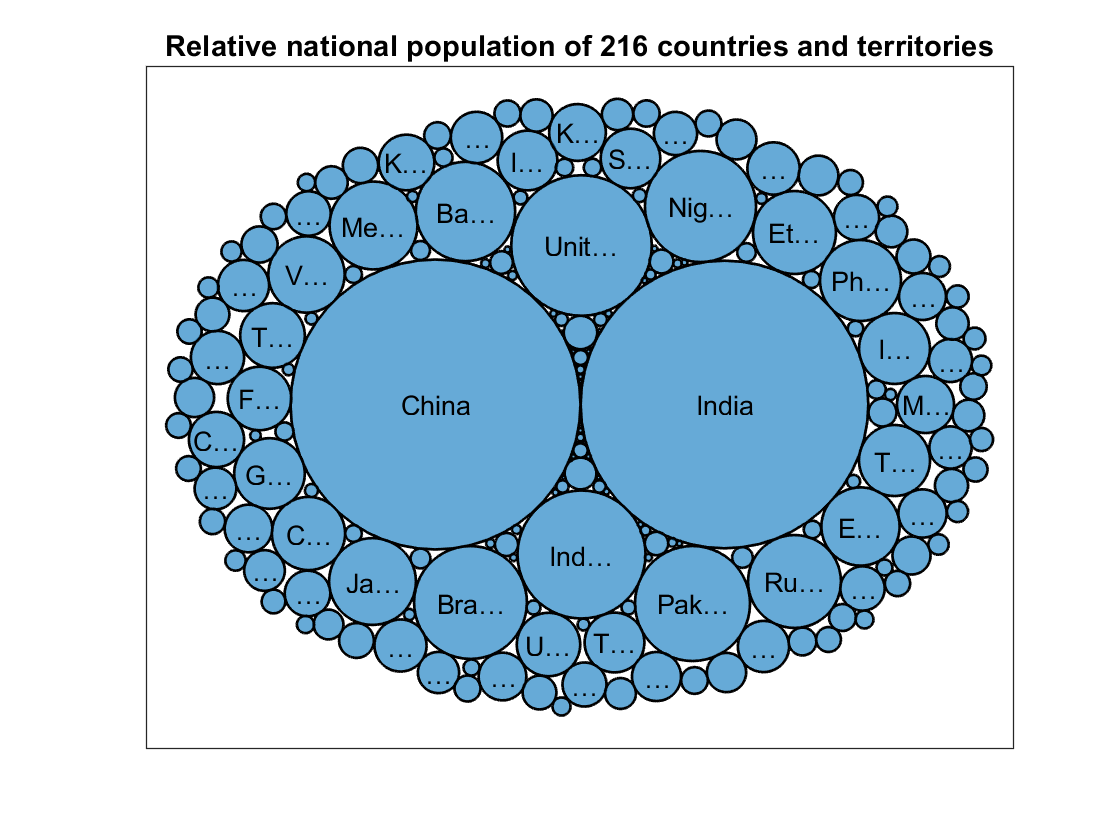

bubblecloud(populationData,"Population","Country");
title("Relative national population of 216 countries and territories")

## Customization

### Group Bubbles Using a Group Variable

Instead of one large group of bubbles, split the bubbles into smaller groups based on the region that the country or territory is in. This improves the visualization of the data by conveying more information and improving readability.

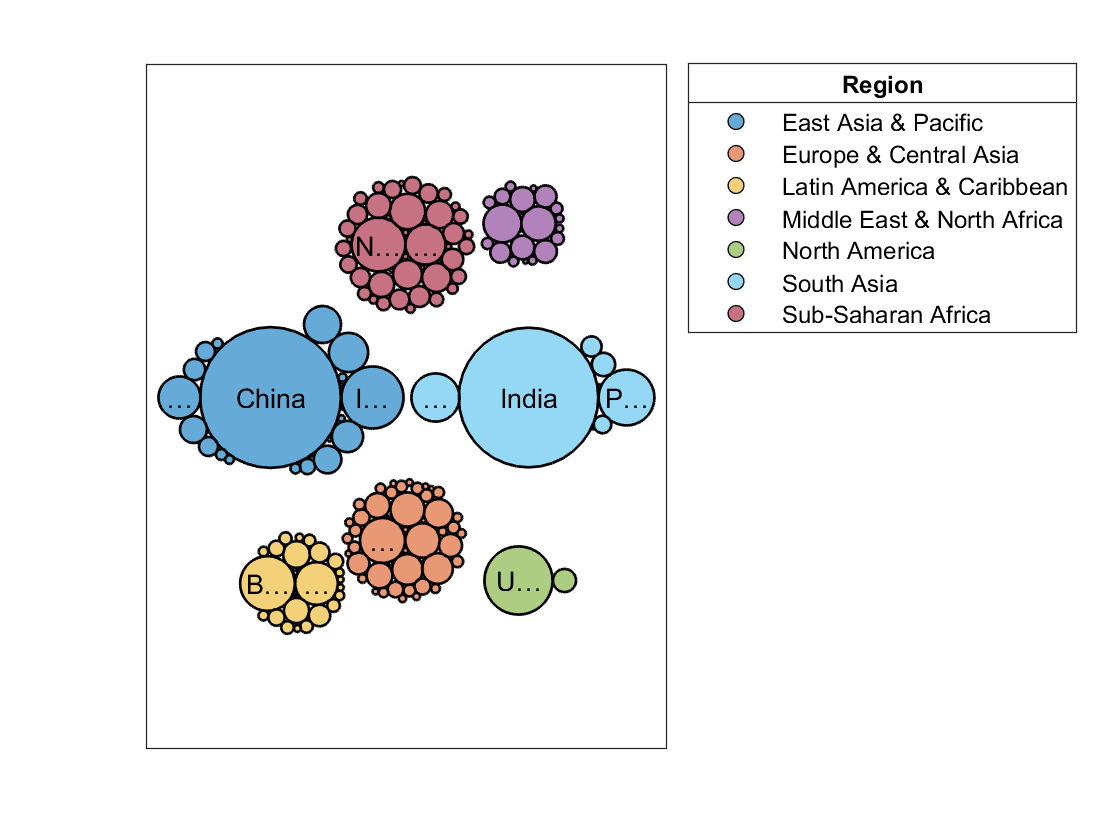

figure
b = bubblecloud(populationData,"Population","Country",...
    "Region");  % Specify the grouping variable as the 4th input argument

### Customize Bubble Appearance

Use dot notation to access and modify the *EdgeColor *and *FontSize p*roperties of the BubbleCloud Object generated from a call to the `bubblecloud` function. Specifying the *EdgeColor* property as flat makes the edges of the bubbles use the same color.

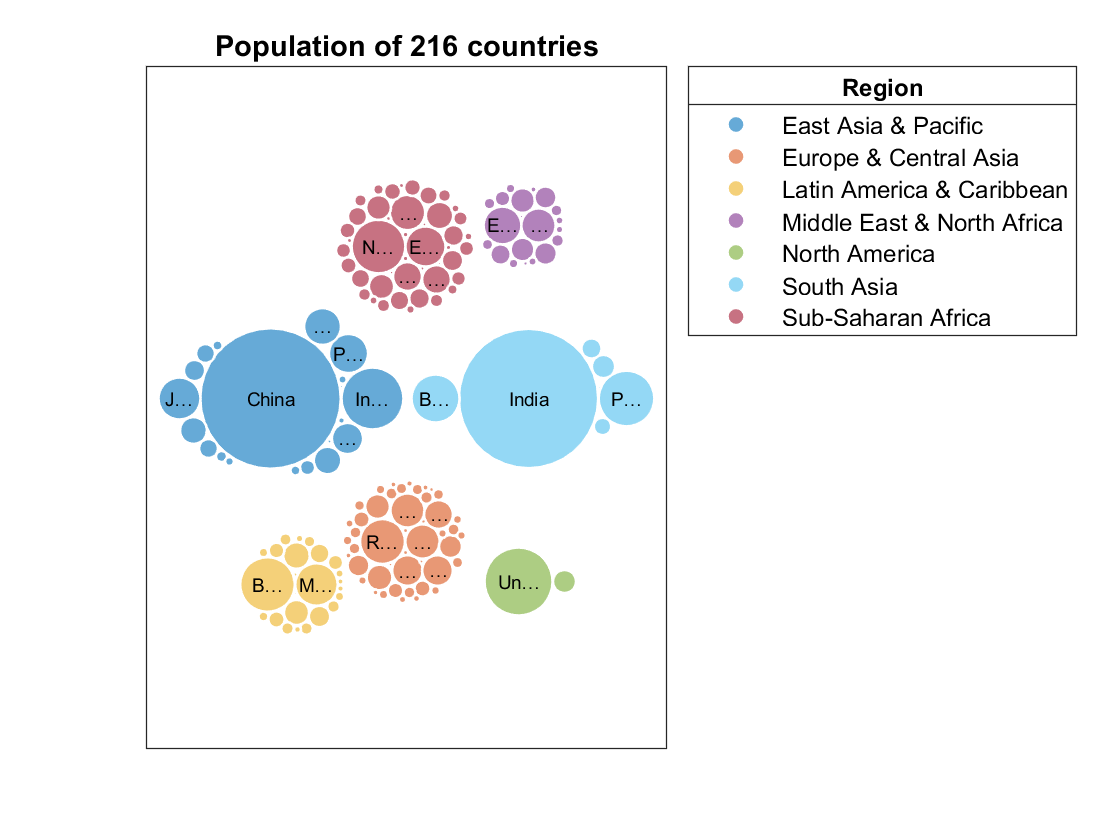

FontSize = 7;

b.EdgeColor = "white";  % Specify edge color as flat 
b.FontSize = FontSize; % Specify the font size
title("Population of 216 countries")

## **Additional Information**

### **Get All BubbleCloud Properties**

Graphics objects in MATLAB have many properties. To see all the properties of a BubbleCloud Object, uncomment the following line of code.

% get(b)

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[bubblecloud](https://www.mathworks.com/help/matlab/ref/bubblecloud.html)

Copyright (c) 2021, The MathWorks, Inc.